rng(42);

% Number of samples and features
numSamples = 100;
numFeaturesX = 50;
numFeaturesY = 200;
numFeaturesZ = 30;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

% Sparsity regularization parameters
cu = 5;
cv = 5;
cw = 5;
% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

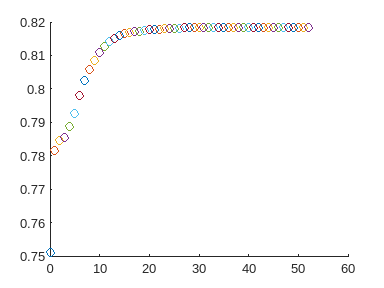

SPLS: itr: 53    diff: 9.84e-06    dim_u: 44    dim_v: 42


[u, v, success] = cv_spls(X, Y, cu, cv, e, itr_lim);

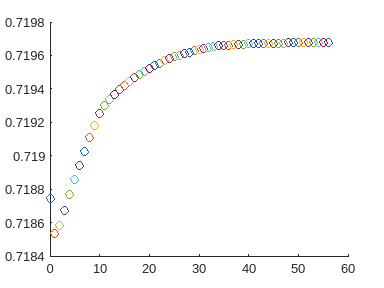

SPLS: itr: 57    diff: 9.51e-06    dim_u: 40    dim_v: 30


[u1, w1, success] = cv_spls(X, Z, cu, cw, e, itr_lim);

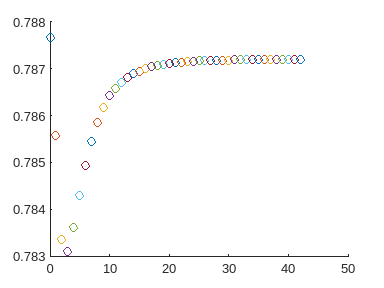

SPLS: itr: 43    diff: 8.63e-06    dim_u: 39    dim_v: 30


[v2, w2, success] = cv_spls(Y, Z, cv, cw, e, itr_lim);

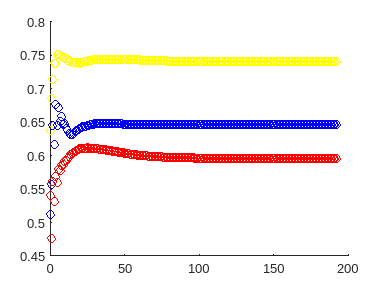

SPLS: itr: 193    diff: 9.71e-06    dim_M1: 41    dim_M2: 38    dim_M3: 30    


matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances, success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);

rng(42);

% Number of samples and features
numSamples = 100;
numFeaturesX = 50;
numFeaturesY = 200;
numFeaturesZ = 30;

% Generate random data matrices X, Y, Z
X = randn(size(gX_table_s));
Y = randn(size(gY_table_s));
Z = randn(size(gZ_table_s));
%%
%% gsPLS prep
%matrices{1} = table2array(gX_table_s);
%matrices{2} = table2array(gY_table_s);
%matrices{3} = table2array(gZ_table_s);
matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cu = 2;
cv = 2;
cw = 2;
e = 1e-5;
itr_lim = 1000;
cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

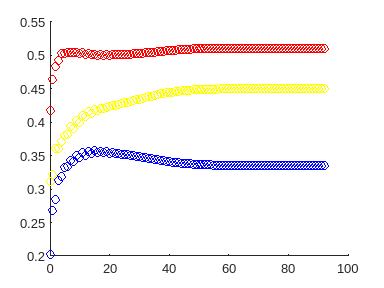

SPLS: itr: 93    diff: 9.51e-06    dim_M1: 34    dim_M2: 8    dim_M3: 28    


cu = 5;
cv = 2;
cw = 10;
e = 1e-5;
itr_lim = 1000;
cs = [cu, cv, cw];
% Run generalized SPLS
[weights, covariances, success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);

result_table = cell2table(cell(0,11), 'VariableNames',{'cu', 'cv', 'cw', 'corr_XY', 'corr_XZ', 'corr_YZ', 'spls_itr', 'diff', 'dim_m1', 'dim_m2', 'dim_m3'});
cu_range = 1:1:sqrt(size(matrices{1},2));
cv_range = 1:1:sqrt(size(matrices{2},2));
cw_range = 1:1:sqrt(size(matrices{3},2));
combi_idx = 0;
for i=1:length(cu_range)
    for j=1:length(cv_range)
        for k=1:length(cw_range)
            cu = cu_range(i);
            cv = cv_range(j);
            cw = cw_range(k);
            combi_idx = combi_idx+1;
            cs = [cu, cv, cw];
            % Run generalized SPLS
            [weights, covariances, success, spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);
            corr_XY = corr(matrices{1}*weights{1},matrices{2}*weights{2});
            corr_XZ = corr(matrices{1}*weights{1},matrices{3}*weights{3});
            corr_YZ = corr(matrices{2}*weights{2},matrices{3}*weights{3});
            result_table.cu(combi_idx) = cu; 
            result_table.cv(combi_idx) = cv; 
            result_table.cw(combi_idx) = cw; 
            result_table.corr_XY(combi_idx) = corr_XY;
            result_table.corr_XZ(combi_idx) = corr_XZ;
            result_table.corr_YZ(combi_idx) = corr_YZ;
            result_table.spls_itr(combi_idx) = spls_itr; 
            result_table.diff(combi_idx) = diff; 
            result_table.dim_m1(combi_idx) = dim_Ms(1);
            result_table.dim_m2(combi_idx) = dim_Ms(2);
            result_table.dim_m3(combi_idx) = dim_Ms(3);
        end
    end
end

SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 1    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 1    dim_M2: 1    dim_M3: 5    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 1    dim_M2: 1    dim_M3: 14    


SPLS: itr: 1001    diff: 1.28e+00    dim_M1: 1    dim_M2: 1    dim_M3: 24    


SPLS: itr: 1001    diff: 1.23e+00    dim_M1: 1    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.32e+00    dim_M1: 1    dim_M2: 8    dim_M3: 1    


SPLS: itr: 1001    diff: 1.36e+00    dim_M1: 1    dim_M2: 8    dim_M3: 7    


SPLS: itr: 1001    diff: 1.21e+00    dim_M1: 1    dim_M2: 7    dim_M3: 13    


SPLS: itr: 1001    diff: 1.04e+00    dim_M1: 1    dim_M2: 8    dim_M3: 24    


SPLS: itr: 1001    diff: 1.02e+00    dim_M1: 1    dim_M2: 8    dim_M3: 28    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 5    dim_M2: 1    dim_M3: 1    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 9    dim_M2: 1    dim_M3: 9    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 10    dim_M2: 1    dim_M3: 18    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 9    dim_M2: 1    dim_M3: 25    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 9    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.33e+00    dim_M1: 7    dim_M2: 8    dim_M3: 1    


SPLS: itr: 1001    diff: 9.76e-01    dim_M1: 7    dim_M2: 6    dim_M3: 6    


SPLS: itr: 52    diff: 8.95e-06    dim_M1: 7    dim_M2: 8    dim_M3: 16    


SPLS: itr: 244    diff: 9.30e-06    dim_M1: 6    dim_M2: 5    dim_M3: 24    


SPLS: itr: 198    diff: 9.24e-06    dim_M1: 6    dim_M2: 5    dim_M3: 28    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 17    dim_M2: 1    dim_M3: 1    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 17    dim_M2: 1    dim_M3: 11    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 17    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 15    dim_M2: 1    dim_M3: 25    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 14    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.34e+00    dim_M1: 14    dim_M2: 8    dim_M3: 1    


SPLS: itr: 58    diff: 8.66e-06    dim_M1: 15    dim_M2: 6    dim_M3: 6    


SPLS: itr: 126    diff: 9.89e-06    dim_M1: 14    dim_M2: 6    dim_M3: 16    


SPLS: itr: 167    diff: 9.89e-06    dim_M1: 13    dim_M2: 5    dim_M3: 28    


SPLS: itr: 109    diff: 9.47e-06    dim_M1: 15    dim_M2: 8    dim_M3: 28    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 28    dim_M2: 1    dim_M3: 1    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 25    dim_M2: 1    dim_M3: 10    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 23    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 24    dim_M2: 1    dim_M3: 25    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 25    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.36e+00    dim_M1: 31    dim_M2: 8    dim_M3: 1    


SPLS: itr: 64    diff: 9.86e-06    dim_M1: 25    dim_M2: 6    dim_M3: 7    


SPLS: itr: 62    diff: 7.16e-06    dim_M1: 29    dim_M2: 5    dim_M3: 17    


SPLS: itr: 96    diff: 8.92e-06    dim_M1: 22    dim_M2: 8    dim_M3: 23    


SPLS: itr: 99    diff: 9.22e-06    dim_M1: 22    dim_M2: 8    dim_M3: 28    


SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 41    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.31e+00    dim_M1: 46    dim_M2: 1    dim_M3: 5    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 42    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 42    dim_M2: 1    dim_M3: 24    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 42    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.20e+00    dim_M1: 45    dim_M2: 8    dim_M3: 1    


SPLS: itr: 66    diff: 8.68e-06    dim_M1: 46    dim_M2: 6    dim_M3: 6    


SPLS: itr: 73    diff: 9.41e-06    dim_M1: 49    dim_M2: 5    dim_M3: 17    


SPLS: itr: 100    diff: 9.51e-06    dim_M1: 34    dim_M2: 8    dim_M3: 28    


SPLS: itr: 93    diff: 9.51e-06    dim_M1: 34    dim_M2: 8    dim_M3: 28    


SPLS: itr: 1001    diff: 1.39e+00    dim_M1: 64    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.30e+00    dim_M1: 65    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 60    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 62    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 60    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.19e+00    dim_M1: 61    dim_M2: 8    dim_M3: 1    


SPLS: itr: 76    diff: 8.21e-06    dim_M1: 63    dim_M2: 6    dim_M3: 6    


SPLS: itr: 99    diff: 9.35e-06    dim_M1: 64    dim_M2: 5    dim_M3: 18    


SPLS: itr: 234    diff: 9.63e-06    dim_M1: 61    dim_M2: 8    dim_M3: 28    


SPLS: itr: 370    diff: 9.75e-06    dim_M1: 62    dim_M2: 8    dim_M3: 28    


SPLS: itr: 1001    diff: 1.36e+00    dim_M1: 75    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.29e+00    dim_M1: 86    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 80    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 83    dim_M2: 1    dim_M3: 27    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 82    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.18e+00    dim_M1: 78    dim_M2: 8    dim_M3: 1    


SPLS: itr: 110    diff: 9.92e-06    dim_M1: 83    dim_M2: 6    dim_M3: 8    


SPLS: itr: 171    diff: 9.19e-06    dim_M1: 81    dim_M2: 7    dim_M3: 13    


SPLS: itr: 138    diff: 9.89e-06    dim_M1: 82    dim_M2: 8    dim_M3: 26    


SPLS: itr: 174    diff: 9.81e-06    dim_M1: 83    dim_M2: 7    dim_M3: 28    


SPLS: itr: 1001    diff: 1.33e+00    dim_M1: 102    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.27e+00    dim_M1: 104    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 107    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 113    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 110    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.17e+00    dim_M1: 102    dim_M2: 8    dim_M3: 1    


SPLS: itr: 178    diff: 9.51e-06    dim_M1: 121    dim_M2: 7    dim_M3: 6    


SPLS: itr: 573    diff: 9.97e-06    dim_M1: 106    dim_M2: 7    dim_M3: 14    


SPLS: itr: 151    diff: 9.57e-06    dim_M1: 110    dim_M2: 7    dim_M3: 26    


SPLS: itr: 308    diff: 1.00e-05    dim_M1: 108    dim_M2: 7    dim_M3: 28    


SPLS: itr: 1001    diff: 1.31e+00    dim_M1: 124    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.25e+00    dim_M1: 131    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 134    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 133    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 137    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.16e+00    dim_M1: 135    dim_M2: 8    dim_M3: 1    


SPLS: itr: 95    diff: 9.21e-06    dim_M1: 136    dim_M2: 8    dim_M3: 6    


SPLS: itr: 218    diff: 9.89e-06    dim_M1: 127    dim_M2: 7    dim_M3: 14    


SPLS: itr: 142    diff: 9.70e-06    dim_M1: 128    dim_M2: 7    dim_M3: 27    


SPLS: itr: 208    diff: 9.41e-06    dim_M1: 131    dim_M2: 6    dim_M3: 28    


SPLS: itr: 1001    diff: 1.30e+00    dim_M1: 154    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.25e+00    dim_M1: 157    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 155    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 162    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 161    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.15e+00    dim_M1: 155    dim_M2: 8    dim_M3: 1    


SPLS: itr: 147    diff: 9.88e-06    dim_M1: 172    dim_M2: 8    dim_M3: 7    


SPLS: itr: 188    diff: 9.79e-06    dim_M1: 156    dim_M2: 7    dim_M3: 14    


SPLS: itr: 169    diff: 9.65e-06    dim_M1: 155    dim_M2: 7    dim_M3: 26    


SPLS: itr: 195    diff: 9.28e-06    dim_M1: 160    dim_M2: 6    dim_M3: 28    


SPLS: itr: 1001    diff: 1.31e+00    dim_M1: 174    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.25e+00    dim_M1: 174    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.17e+00    dim_M1: 174    dim_M2: 8    dim_M3: 1    


SPLS: itr: 152    diff: 9.65e-06    dim_M1: 174    dim_M2: 8    dim_M3: 7    


SPLS: itr: 267    diff: 9.98e-06    dim_M1: 174    dim_M2: 7    dim_M3: 14    


SPLS: itr: 189    diff: 9.67e-06    dim_M1: 174    dim_M2: 7    dim_M3: 26    


SPLS: itr: 151    diff: 9.60e-06    dim_M1: 174    dim_M2: 6    dim_M3: 28    


SPLS: itr: 1001    diff: 1.31e+00    dim_M1: 174    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.25e+00    dim_M1: 174    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.17e+00    dim_M1: 174    dim_M2: 8    dim_M3: 1    


SPLS: itr: 152    diff: 9.67e-06    dim_M1: 174    dim_M2: 8    dim_M3: 7    


SPLS: itr: 268    diff: 9.75e-06    dim_M1: 174    dim_M2: 7    dim_M3: 14    


SPLS: itr: 189    diff: 9.66e-06    dim_M1: 174    dim_M2: 7    dim_M3: 26    


SPLS: itr: 151    diff: 9.60e-06    dim_M1: 174    dim_M2: 6    dim_M3: 28    


SPLS: itr: 1001    diff: 1.31e+00    dim_M1: 174    dim_M2: 1    dim_M3: 1    


SPLS: itr: 1001    diff: 1.25e+00    dim_M1: 174    dim_M2: 1    dim_M3: 6    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 19    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 26    


SPLS: itr: 2    diff: 0.00e+00    dim_M1: 174    dim_M2: 1    dim_M3: 28    


SPLS: itr: 1001    diff: 1.17e+00    dim_M1: 174    dim_M2: 8    dim_M3: 1    


SPLS: itr: 152    diff: 9.67e-06    dim_M1: 174    dim_M2: 8    dim_M3: 7    


SPLS: itr: 268    diff: 9.75e-06    dim_M1: 174    dim_M2: 7    dim_M3: 14    


SPLS: itr: 189    diff: 9.66e-06    dim_M1: 174    dim_M2: 7    dim_M3: 26    


SPLS: itr: 151    diff: 9.60e-06    dim_M1: 174    dim_M2: 6    dim_M3: 28    
